%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


pose_f = [0 1 0];   % Final Pose
v_end = 0.15;       % Start and end linear velocity
E_max = 300;        % Maximum energy consumption


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Defining equations and constants

syms a0 a1 a2 a3 a4 a5 b0 b1 b2 b3 b4 b5 r d t

% Symbolic equations
eqns.x = a0 + a1*t + a2*t^2 + a3*t^3 + a4*t^4 + a5*t^5;
eqns.y = b0 + b1*t + b2*t^2 + b3*t^3 + b4*t^4 + b5*t^5;

% eqns.v = sqrt((eqns.x_dot^2) + (eqns.y_dot^2));
eqns.v = sqrt((5*a5*t^4 + 4*a4*t^3 + 3*a3*t^2 + 2*a2*t + a1)^2 + (5*b5*t^4 + 4*b4*t^3 + 3*b3*t^2 + 2*b2*t + b1)^2);

% eqns.psi = atan2(eqns.y_dot,eqns.x_dot);
% eqns.omega = diff(atan(eqns.y_dot/eqns.x_dot),t);
eqns.psi = atan2(5*b5*t^4 + 4*b4*t^3 + 3*b3*t^2 + 2*b2*t + b1, 5*a5*t^4 + 4*a4*t^3 + 3*a3*t^2 + 2*a2*t + a1);
eqns.omega = ((20*b5*t^3 + 12*b4*t^2 + 6*b3*t + 2*b2)/(5*a5*t^4 + 4*a4*t^3 + 3*a3*t^2 + 2*a2*t + a1) - ((20*a5*t^3 + 12*a4*t^2 + 6*a3*t + 2*a2)*(5*b5*t^4 + 4*b4*t^3 + 3*b3*t^2 + 2*b2*t + b1))/(5*a5*t^4 + 4*a4*t^3 + 3*a3*t^2 + 2*a2*t + a1)^2)/((5*b5*t^4 + 4*b4*t^3 + 3*b3*t^2 + 2*b2*t + b1)^2/(5*a5*t^4 + 4*a4*t^3 + 3*a3*t^2 + 2*a2*t + a1)^2 + 1);

% eqns.phiL_dot = (eqns.v/r) - ((d*eqns.omega)/(2*r));
% eqns.phiR_dot = (eqns.v/r) + ((d*eqns.omega)/(2*r));
% eqns.phiL_ddot = diff(eqns.phiL_dot);
% eqns.phiR_ddot = diff(eqns.phiR_dot);
eqns.phiL_dot = sqrt((5*a5*t^4 + 4*a4*t^3 + 3*a3*t^2 + 2*a2*t + a1)^2 + (5*b5*t^4 + 4*b4*t^3 + 3*b3*t^2 + 2*b2*t + b1)^2)/r - (d*((20*b5*t^3 + 12*b4*t^2 + 6*b3*t + 2*b2)/(5*a5*t^4 + 4*a4*t^3 + 3*a3*t^2 + 2*a2*t + a1) - ((20*a5*t^3 + 12*a4*t^2 + 6*a3*t + 2*a2)*(5*b5*t^4 + 4*b4*t^3 + 3*b3*t^2 + 2*b2*t + b1))/(5*a5*t^4 + 4*a4*t^3 + 3*a3*t^2 + 2*a2*t + a1)^2))/(2*r*((5*b5*t^4 + 4*b4*t^3 + 3*b3*t^2 + 2*b2*t + b1)^2/(5*a5*t^4 + 4*a4*t^3 + 3*a3*t^2 + 2*a2*t + a1)^2 + 1));
eqns.phiR_dot = sqrt((5*a5*t^4 + 4*a4*t^3 + 3*a3*t^2 + 2*a2*t + a1)^2 + (5*b5*t^4 + 4*b4*t^3 + 3*b3*t^2 + 2*b2*t + b1)^2)/r + (d*((20*b5*t^3 + 12*b4*t^2 + 6*b3*t + 2*b2)/(5*a5*t^4 + 4*a4*t^3 + 3*a3*t^2 + 2*a2*t + a1) - ((20*a5*t^3 + 12*a4*t^2 + 6*a3*t + 2*a2)*(5*b5*t^4 + 4*b4*t^3 + 3*b3*t^2 + 2*b2*t + b1))/(5*a5*t^4 + 4*a4*t^3 + 3*a3*t^2 + 2*a2*t + a1)^2))/(2*r*((5*b5*t^4 + 4*b4*t^3 + 3*b3*t^2 + 2*b2*t + b1)^2/(5*a5*t^4 + 4*a4*t^3 + 3*a3*t^2 + 2*a2*t + a1)^2 + 1));
eqns.phiL_ddot = (2*(20*a5*t^3 + 12*a4*t^2 + 6*a3*t + 2*a2)*(5*a5*t^4 + 4*a4*t^3 + 3*a3*t^2 + 2*a2*t + a1) + 2*(20*b5*t^3 + 12*b4*t^2 + 6*b3*t + 2*b2)*(5*b5*t^4 + 4*b4*t^3 + 3*b3*t^2 + 2*b2*t + b1))/(2*r*sqrt((5*a5*t^4 + 4*a4*t^3 + 3*a3*t^2 + 2*a2*t + a1)^2 + (5*b5*t^4 + 4*b4*t^3 + 3*b3*t^2 + 2*b2*t + b1)^2)) - (d*((60*b5*t^2 + 24*b4*t + 6*b3)/(5*a5*t^4 + 4*a4*t^3 + 3*a3*t^2 + 2*a2*t + a1) + (2*(20*a5*t^3 + 12*a4*t^2 + 6*a3*t + 2*a2)^2*(5*b5*t^4 + 4*b4*t^3 + 3*b3*t^2 + 2*b2*t + b1))/(5*a5*t^4 + 4*a4*t^3 + 3*a3*t^2 + 2*a2*t + a1)^3 - ((60*a5*t^2 + 24*a4*t + 6*a3)*(5*b5*t^4 + 4*b4*t^3 + 3*b3*t^2 + 2*b2*t + b1))/(5*a5*t^4 + 4*a4*t^3 + 3*a3*t^2 + 2*a2*t + a1)^2 - (2*(20*a5*t^3 + 12*a4*t^2 + 6*a3*t + 2*a2)*(20*b5*t^3 + 12*b4*t^2 + 6*b3*t + 2*b2))/(5*a5*t^4 + 4*a4*t^3 + 3*a3*t^2 + 2*a2*t + a1)^2))/(2*r*((5*b5*t^4 + 4*b4*t^3 + 3*b3*t^2 + 2*b2*t + b1)^2/(5*a5*t^4 + 4*a4*t^3 + 3*a3*t^2 + 2*a2*t + a1)^2 + 1)) - (d*((2*(20*a5*t^3 + 12*a4*t^2 + 6*a3*t + 2*a2)*(5*b5*t^4 + 4*b4*t^3 + 3*b3*t^2 + 2*b2*t + b1)^2)/(5*a5*t^4 + 4*a4*t^3 + 3*a3*t^2 + 2*a2*t + a1)^3 - (2*(20*b5*t^3 + 12*b4*t^2 + 6*b3*t + 2*b2)*(5*b5*t^4 + 4*b4*t^3 + 3*b3*t^2 + 2*b2*t + b1))/(5*a5*t^4 + 4*a4*t^3 + 3*a3*t^2 + 2*a2*t + a1)^2)*((20*b5*t^3 + 12*b4*t^2 + 6*b3*t + 2*b2)/(5*a5*t^4 + 4*a4*t^3 + 3*a3*t^2 + 2*a2*t + a1) - ((20*a5*t^3 + 12*a4*t^2 + 6*a3*t + 2*a2)*(5*b5*t^4 + 4*b4*t^3 + 3*b3*t^2 + 2*b2*t + b1))/(5*a5*t^4 + 4*a4*t^3 + 3*a3*t^2 + 2*a2*t + a1)^2))/(2*r*((5*b5*t^4 + 4*b4*t^3 + 3*b3*t^2 + 2*b2*t + b1)^2/(5*a5*t^4 + 4*a4*t^3 + 3*a3*t^2 + 2*a2*t + a1)^2 + 1)^2);
eqns.phiR_ddot = (2*(20*a5*t^3 + 12*a4*t^2 + 6*a3*t + 2*a2)*(5*a5*t^4 + 4*a4*t^3 + 3*a3*t^2 + 2*a2*t + a1) + 2*(20*b5*t^3 + 12*b4*t^2 + 6*b3*t + 2*b2)*(5*b5*t^4 + 4*b4*t^3 + 3*b3*t^2 + 2*b2*t + b1))/(2*r*sqrt((5*a5*t^4 + 4*a4*t^3 + 3*a3*t^2 + 2*a2*t + a1)^2 + (5*b5*t^4 + 4*b4*t^3 + 3*b3*t^2 + 2*b2*t + b1)^2)) + (d*((60*b5*t^2 + 24*b4*t + 6*b3)/(5*a5*t^4 + 4*a4*t^3 + 3*a3*t^2 + 2*a2*t + a1) + (2*(20*a5*t^3 + 12*a4*t^2 + 6*a3*t + 2*a2)^2*(5*b5*t^4 + 4*b4*t^3 + 3*b3*t^2 + 2*b2*t + b1))/(5*a5*t^4 + 4*a4*t^3 + 3*a3*t^2 + 2*a2*t + a1)^3 - ((60*a5*t^2 + 24*a4*t + 6*a3)*(5*b5*t^4 + 4*b4*t^3 + 3*b3*t^2 + 2*b2*t + b1))/(5*a5*t^4 + 4*a4*t^3 + 3*a3*t^2 + 2*a2*t + a1)^2 - (2*(20*a5*t^3 + 12*a4*t^2 + 6*a3*t + 2*a2)*(20*b5*t^3 + 12*b4*t^2 + 6*b3*t + 2*b2))/(5*a5*t^4 + 4*a4*t^3 + 3*a3*t^2 + 2*a2*t + a1)^2))/(2*r*((5*b5*t^4 + 4*b4*t^3 + 3*b3*t^2 + 2*b2*t + b1)^2/(5*a5*t^4 + 4*a4*t^3 + 3*a3*t^2 + 2*a2*t + a1)^2 + 1)) + (d*((2*(20*a5*t^3 + 12*a4*t^2 + 6*a3*t + 2*a2)*(5*b5*t^4 + 4*b4*t^3 + 3*b3*t^2 + 2*b2*t + b1)^2)/(5*a5*t^4 + 4*a4*t^3 + 3*a3*t^2 + 2*a2*t + a1)^3 - (2*(20*b5*t^3 + 12*b4*t^2 + 6*b3*t + 2*b2)*(5*b5*t^4 + 4*b4*t^3 + 3*b3*t^2 + 2*b2*t + b1))/(5*a5*t^4 + 4*a4*t^3 + 3*a3*t^2 + 2*a2*t + a1)^2)*((20*b5*t^3 + 12*b4*t^2 + 6*b3*t + 2*b2)/(5*a5*t^4 + 4*a4*t^3 + 3*a3*t^2 + 2*a2*t + a1) - ((20*a5*t^3 + 12*a4*t^2 + 6*a3*t + 2*a2)*(5*b5*t^4 + 4*b4*t^3 + 3*b3*t^2 + 2*b2*t + b1))/(5*a5*t^4 + 4*a4*t^3 + 3*a3*t^2 + 2*a2*t + a1)^2))/(2*r*((5*b5*t^4 + 4*b4*t^3 + 3*b3*t^2 + 2*b2*t + b1)^2/(5*a5*t^4 + 4*a4*t^3 + 3*a3*t^2 + 2*a2*t + a1)^2 + 1)^2);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Robot physical dimentions
r = 0.1;      % wheel radius
d = 0.33;       % wheelbase
l = d/2;          % Distance from wheels to axis of symmetry
c = r/(2*l);    % Geometric constant

% DC motor constants
Tm = 0.359;         % Constant friction torque
n = 19.7;              % gear ratio
Kt = 0.069;         % torque constant
Kv = 0.069;         % voltage constant
R = 2.74;              % armature resistance
upsilon = 0.0017;    % viscous damping coefficient

% Robot system masses
m_c = 21.2;         % Body mass (no wheels or motor rotors)
m_w = 1.39;         % 1 Wheel and rotor mass
m = m_c + 2*m_w;     % total robot mass

% Robot system moments of inertia
I_c = (1/2)*m_c*l^2;                            % Robot body (no wheels or motor rotors)
I_w = (1/2)*m_w*r^2;                             % Wheels about rotation axis
I_m = (1/4)*m_w*r^2 + (1/12)*m_w*(0.02^2);      % Wheels about diameter
I_s = 0.000026127698;                           % equivalent of motors
I = I_c + 2*m_w*l^2 + 2*I_m;                    % total

% Matrices that remain constant
T = [   0       0;
        0       0;
        Kt*n/R  0;
        0       Kt*n/R];

M = [   m       0       0                   0;
        0       m       0                   0;
        0       0       (I*c^2)+I_w+I_s    -I*c^2;
        0       0       -I*c^2              (I*c^2)+I_w+I_s];

F = [   0       0       0                           0;
        0       0       0                           0;
        0       0       ((Kt*Kv*n^2)/(R))+upsilon   0;
        0       0       0                           ((Kt*Kv*n^2)/(R))+upsilon];

C = [0;0;Tm;Tm];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Solve
dt = 0.001;
options = optimoptions("fmincon",...
    "Algorithm","interior-point",...
    "SubproblemAlgorithm","cg",...
    "ConstraintTolerance",0.001);
[solution,objectiveValue,exitflag] = fmincon(@(optimInput)objectiveFcn(optimInput),[1 1 -1],[],[],[],[],[],[],...
    @(optimInput)constraintFcn(pose_f, v_end, E_max, T, M, F, C, c, l, r, d, R, n, Kv, dt, eqns, optimInput), options);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



T_f = solution(1)

t_f = 2.2690

t = 0:dt:T_f;
eta_vals = [v_end*T_f v_end*T_f solution(2:3)];

[x5, y5, v, psi, omega, phiL_dot, phiR_dot, V, i, P, E] = generate5order(pose_f, T, M, F, C, c, l, r, d, R, n, Kv, dt, T_f, eqns, eta_vals);

E

E = 300.0000

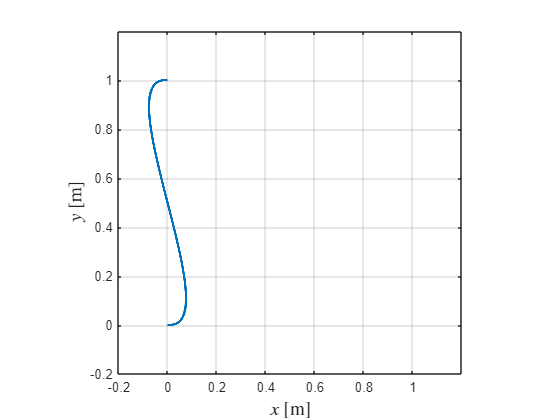


figure(2), clf
plot(x5, y5, LineWidth=2)
pbaspect([1 1 1])
xlim([-0.2 1.2])
ylim([-0.2 1.2])
xlabel("$x$ [m]",fontsize=14, Interpreter="latex")
ylabel("$y$ [m]",fontsize=14, Interpreter="latex")
grid on
set(gca, 'xtick', -0.4:0.2:1.6)
set(gca, 'ytick', -0.4:0.2:1.6)

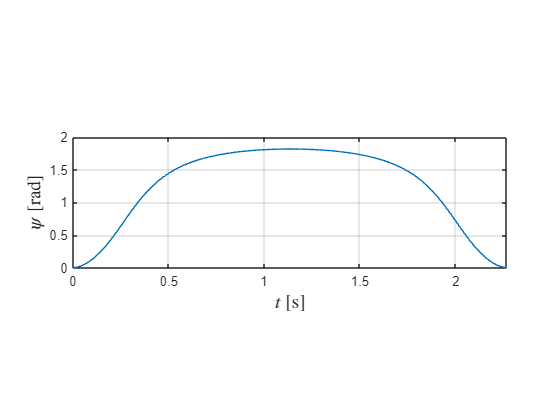


figure(3), clf
plot(t, psi)
pbaspect([10 3 1])
xlabel("$t$ [s]",fontsize=14, Interpreter="latex")
ylabel("$\psi$ [rad]",fontsize=14, Interpreter="latex")
xlim([0 t_f])
grid on

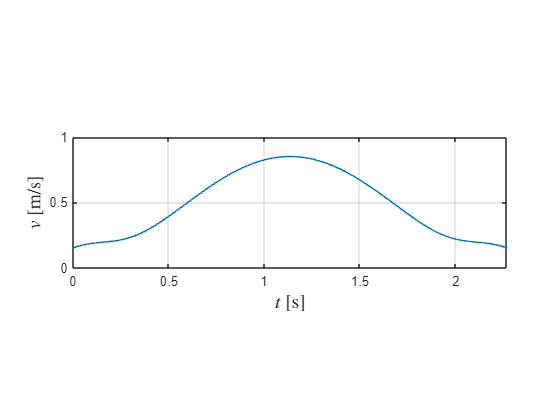


figure(4),clf
plot(t, v)
pbaspect([10 3 1])
xlabel("$t$ [s]",fontsize=14, Interpreter="latex")
ylabel("$v$ [m/s]",fontsize=14, Interpreter="latex")
xlim([0 t_f])
grid on

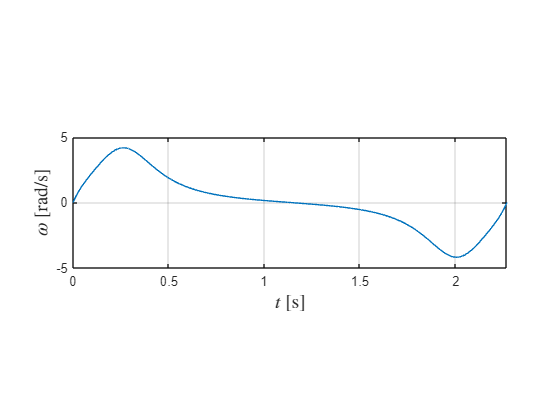


figure(5), clf
plot(t, omega)
pbaspect([10 3 1])
xlabel("$t$ [s]",fontsize=14, Interpreter="latex")
ylabel("$\omega$ [rad/s]",fontsize=14, Interpreter="latex")
xlim([0 t_f])
grid on

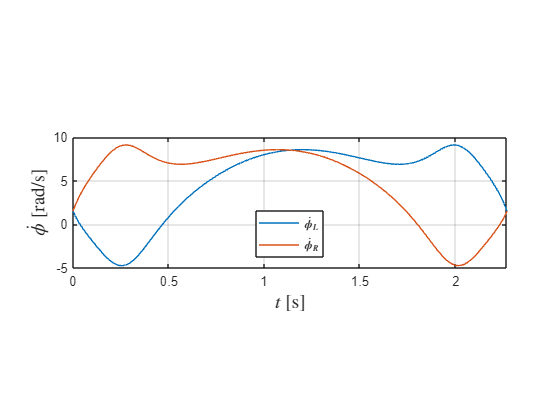


figure(6), clf
plot(t, phiL_dot, t, phiR_dot)
pbaspect([10 3 1])
xlabel("$t$ [s]",fontsize=14, Interpreter="latex")
ylabel("$\dot{\phi}$ [rad/s]",fontsize=14, Interpreter="latex")
xlim([0 t_f])
legend("$\dot{\phi}_{L}$","$\dot{\phi}_R$",Interpreter="latex",Location="south")
grid on

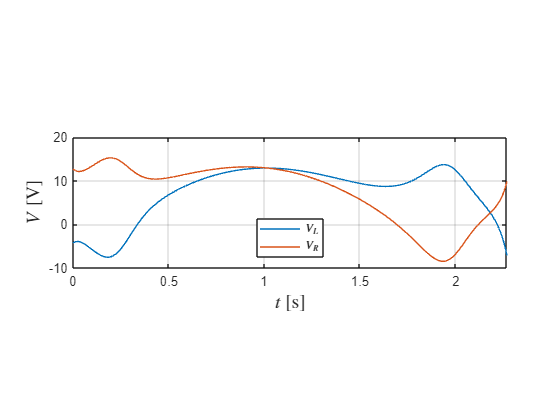


figure(7), clf
plot(t,V(1,:), t, V(2,:))
pbaspect([10 3 1])
xlabel("$t$ [s]",fontsize=14, Interpreter="latex")
ylabel("$V$ [V]",fontsize=14, Interpreter="latex")
xlim([0 t_f])
legend("$V_L$","$V_R$",Interpreter="latex", Location="south")
grid on

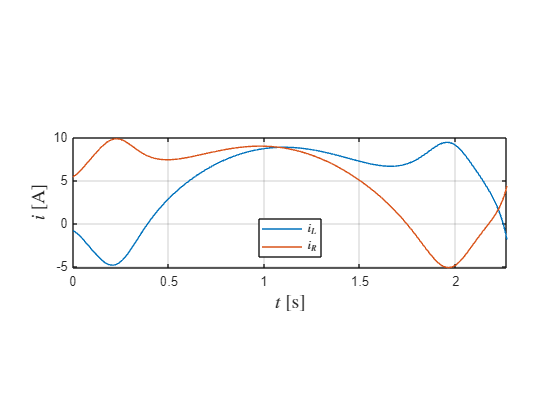


figure(8), clf
plot(t,i(1, :), t, i(2,:))
pbaspect([10 3 1])
xlabel("$t$ [s]",fontsize=14, Interpreter="latex")
ylabel("$i$ [A]",fontsize=14, Interpreter="latex")
xlim([0 t_f])
legend("$i_L$","$i_R$",Interpreter="latex", Location="south")
grid on

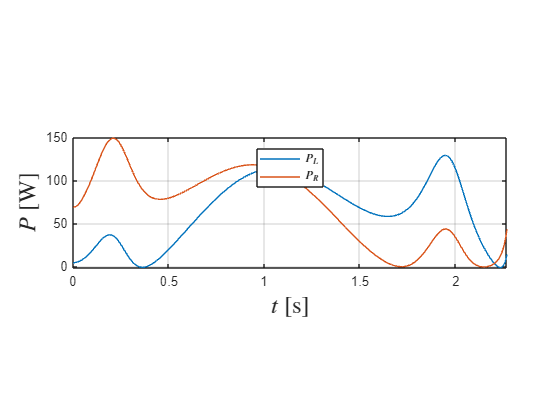


figure(9), clf
plot(t, P(1,:), t, P(2,:))
pbaspect([10 3 1])
xlabel("$t$ [s]",fontsize=18, Interpreter="latex")
ylabel("$P$ [W]",fontsize=18, Interpreter="latex")
xlim([0 t_f])
legend("$P_L$","$P_R$",Interpreter="latex", Location="north")
grid on

function f = objectiveFcn(optimInput) % Cost function to be minimised
t_f = optimInput(1);
f = t_f;
end

% Constraint function containing energy constraints and motor limits
function [c,ceq] = constraintFcn(pose_f, v_end, E_max, T, M, F, C, c, l, r, d, R, n, Kv, dt, eqns, optimInput)
t_f = optimInput(1);
eta1 = v_end*t_f;
eta2 = v_end*t_f;
eta3 = optimInput(2);
eta4 = optimInput(3);

[~, ~, ~, ~, ~, ~, ~, V, ~, ~, E] = generate5order(pose_f, T, M, F, C, c, l, r, d, R, n, Kv, dt, t_f, eqns, [eta1 eta2 eta3 eta4]);

c(1) = E - E_max;
c(2) = -eta1*eta2;
c(3) = max(max(V(1,:)), max(V(2,:))) - 24;

ceq =[];
end

% Function to generate the trajectory and calculate energy consumption
function [x, y, v, psi, omega, phiL_dot, phiR_dot, V, i, P, E] = generate5order(pose_f, T, M, F, C, c, l, r, d, R, n, Kv, dt, t_f, eqns, eta_vals)
% Constants
xA = 0;
yA = 0;
psiA = 0;
kappaA = 0;
kappaB = 0;

eta1 = eta_vals(1);
eta2 = eta_vals(2);
eta3 = eta_vals(3);
eta4 = eta_vals(4);

% Extract final pose information
xB = pose_f(1);
yB = pose_f(2);
psiB = pose_f(3);

% Calculate symbolic variables
t = 0:dt:t_f;

% Calculate polynomial coefficients
a0 = xA;
a1 = (eta1*cos(psiA))/t_f;
a2 = ((1/2)*(eta3*cos(psiA)-(eta1^2)*kappaA*sin(psiA)))/t_f^2;
a3 = (10*(xB-xA) - (6*eta1 +(3/2)*eta3)*cos(psiA)...
    - (4*eta2 - (1/2)*eta4)*cos(psiB) + (3/2)*(eta1^2)*kappaA*sin(psiA)...
    - (1/2)*(eta2^2)*kappaB*sin(psiB))/t_f^3;
a4 = (-15*(xB-xA) + (8*eta1 + (3/2)*eta3)*cos(psiA)...
    + (7*eta2-eta4)*cos(psiB) - (3/2)*(eta1^2)*kappaA*sin(psiA)...
    + (eta2^2)*kappaB*sin(psiB))/t_f^4;
a5 = (6*(xB-xA) - (3*eta1 + (1/2)*eta3)*cos(psiA)...
     - (3*eta2-(1/2)*eta4)*cos(psiB) + (1/2)*(eta1^2)*kappaA*sin(psiA)...
     - (1/2)*(eta2^2)*kappaB*sin(psiB))/t_f^5;

b0 = yA;
b1 = (eta1*sin(psiA))/t_f;
b2 = ((1/2)*(eta3*sin(psiA)-(eta1^2)*kappaA*cos(psiA)))/t_f^2;
b3 = (10*(yB-yA) - (6*eta1 +(3/2)*eta3)*sin(psiA)...
    - (4*eta2 - (1/2)*eta4)*sin(psiB) - (3/2)*(eta1^2)*kappaA*cos(psiA)...
    + (1/2)*(eta2^2)*kappaB*cos(psiB))/t_f^3;
b4 = (-15*(yB-yA) + (8*eta1 + (3/2)*eta3)*sin(psiA)...
    + (7*eta2-eta4)*sin(psiB) + (3/2)*(eta1^2)*kappaA*cos(psiA)...
    - (eta2^2)*kappaB*cos(psiB))/t_f^4;
b5 = (6*(yB-yA) - (3*eta1 + (1/2)*eta3)*sin(psiA)...
     - (3*eta2-(1/2)*eta4)*sin(psiB) - (1/2)*(eta1^2)*kappaA*cos(psiA)...
     + (1/2)*(eta2^2)*kappaB*cos(psiB))/t_f^5;

x = eval(eqns.x);
y = eval(eqns.y);

v = eval(eqns.v);
psi = eval(eqns.psi);

omega = eval(eqns.omega);
% omega_dot = eval(eqns.omega_dot);
phiL_dot = eval(eqns.phiL_dot);
phiR_dot = eval(eqns.phiR_dot);

phiL_ddot = eval(eqns.phiL_ddot);
phiR_ddot = eval(eqns.phiR_ddot);

% tau_L = (v_dot*m*r/2) - (omega_dot*I*r/d);
% tau_R = (v_dot*m*r/2) + (omega_dot*I*r/d);


% Evaluate the curve equations
% x = a0 + a1*t + a2*t.^2 + a3*t.^3 + a4*t.^4 + a5*t.^5 + a6*t.^6 + a7*t.^7;
% y = b0 + b1*t + b2*t.^2 + b3*t.^3 + b4*t.^4 + b5*t.^5 + b6*t.^6 + b7*t.^7;
% v = sqrt((7*a7*t.^6 + 6*a6*t.^5 + 5*a5*t.^4 + 4*a4*t.^3 + 3*a3*t.^2 + 2*a2*t + a1).^2 + (7*b7*t.^6 + 6*b6*t.^5 + 5*b5*t.^4 + 4*b4*t.^3 + 3*b3*t.^2 + 2*b2*t + b1).^2);
% v_dot = (2*(42*a7*t.^5 + 30*a6*t.^4 + 20*a5*t.^3 + 12*a4*t.^2 + 6*a3*t + 2*a2).*(7*a7*t.^6 + 6*a6*t.^5 + 5*a5*t.^4 + 4*a4*t.^3 + 3*a3*t.^2 + 2*a2*t + a1) + 2*(42*b7*t.^5 + 30*b6*t.^4 + 20*b5*t.^3 + 12*b4*t.^2 + 6*b3*t + 2*b2).*(7*b7*t.^6 + 6*b6*t.^5 + 5*b5*t.^4 + 4*b4*t.^3 + 3*b3*t.^2 + 2*b2*t + b1)).*((2*sqrt((7*a7*t.^6 + 6*a6*t.^5 + 5*a5*t.^4 + 4*a4*t.^3 + 3*a3*t.^2 + 2*a2*t + a1).^2 + (7*b7*t.^6 + 6*b6*t.^5 + 5*b5*t.^4 + 4*b4*t.^3 + 3*b3*t.^2 + 2*b2*t + b1).^2)).^(-1));
% 
% psi = atan2(7*b7*t.^6 + 6*b6*t.^5 + 5*b5*t.^4 + 4*b4*t.^3 + 3*b3*t.^2 + 2*b2*t + b1, 7*a7*t.^6 + 6*a6*t.^5 + 5*a5*t.^4 + 4*a4*t.^3 + 3*a3*t.^2 + 2*a2*t + a1);
% omega = ((42*b7*t.^5 + 30*b6*t.^4 + 20*b5*t.^3 + 12*b4*t.^2 + 6*b3*t + 2*b2).*((7*a7*t.^6 + 6*a6*t.^5 + 5*a5*t.^4 + 4*a4*t.^3 + 3*a3*t.^2 + 2*a2*t + a1).^(-1)) - ((42*a7*t.^5 + 30*a6*t.^4 + 20*a5*t.^3 + 12*a4*t.^2 + 6*a3*t + 2*a2).*(7*b7*t.^6 + 6*b6*t.^5 + 5*b5*t.^4 + 4*b4*t.^3 + 3*b3*t.^2 + 2*b2*t + b1)).*((7*a7*t.^6 + 6*a6*t.^5 + 5*a5*t.^4 + 4*a4*t.^3 + 3*a3*t.^2 + 2*a2*t + a1).^(-2)).*((((7*b7*t.^6 + 6*b6*t.^5 + 5*b5*t.^4 + 4*b4*t.^3 + 3*b3*t.^2 + 2*b2*t + b1).^2).*((7*a7*t.^6 + 6*a6*t.^5 + 5*a5*t.^4 + 4*a4*t.^3 + 3*a3*t.^2 + 2*a2*t + a1).^(-2)) + 1).^(-1)));
% omega_dot = ((210*b7*t.^4 + 120*b6*t.^3 + 60*b5*t.^2 + 24*b4*t + 6*b3).*((7*a7*t.^6 + 6*a6*t.^5 + 5*a5*t.^4 + 4*a4*t.^3 + 3*a3*t.^2 + 2*a2*t + a1).^(-1)) + (2*(42*a7*t.^5 + 30*a6*t.^4 + 20*a5*t.^3 + 12*a4*t.^2 + 6*a3*t + 2*a2).^2.*(7*b7*t.^6 + 6*b6*t.^5 + 5*b5*t.^4 + 4*b4*t.^3 + 3*b3*t.^2 + 2*b2*t + b1)).*((7*a7*t.^6 + 6*a6*t.^5 + 5*a5*t.^4 + 4*a4*t.^3 + 3*a3*t.^2 + 2*a2*t + a1).^(-3)) - ((210*a7*t.^4 + 120*a6*t.^3 + 60*a5*t.^2 + 24*a4*t + 6*a3).*(7*b7*t.^6 + 6*b6*t.^5 + 5*b5*t.^4 + 4*b4*t.^3 + 3*b3*t.^2 + 2*b2*t + b1)).*((7*a7*t.^6 + 6*a6*t.^5 + 5*a5*t.^4 + 4*a4*t.^3 + 3*a3*t.^2 + 2*a2*t + a1).^(-2)) - (2*(42*a7*t.^5 + 30*a6*t.^4 + 20*a5*t.^3 + 12*a4*t.^2 + 6*a3*t + 2*a2).*(42*b7*t.^5 + 30*b6*t.^4 + 20*b5*t.^3 + 12*b4*t.^2 + 6*b3*t + 2*b2)).*((7*a7*t.^6 + 6*a6*t.^5 + 5*a5*t.^4 + 4*a4*t.^3 + 3*a3*t.^2 + 2*a2*t + a1).^(-2))).*((((7*b7*t.^6 + 6*b6*t.^5 + 5*b5*t.^4 + 4*b4*t.^3 + 3*b3*t.^2 + 2*b2*t + b1).^2).*((7*a7*t.^6 + 6*a6*t.^5 + 5*a5*t.^4 + 4*a4*t.^3 + 3*a3*t.^2 + 2*a2*t + a1).^(-2)) + 1).^(-1)) - (((42*b7*t.^5 + 30*b6*t.^4 + 20*b5*t.^3 + 12*b4*t.^2 + 6*b3*t + 2*b2).*((7*a7*t.^6 + 6*a6*t.^5 + 5*a5*t.^4 + 4*a4*t.^3 + 3*a3*t.^2 + 2*a2*t + a1).^(-1)) - ((42*a7*t.^5 + 30*a6*t.^4 + 20*a5*t.^3 + 12*a4*t.^2 + 6*a3*t + 2*a2).*(7*b7*t.^6 + 6*b6*t.^5 + 5*b5*t.^4 + 4*b4*t.^3 + 3*b3*t.^2 + 2*b2*t + b1)).*((7*a7*t.^6 + 6*a6*t.^5 + 5*a5*t.^4 + 4*a4*t.^3 + 3*a3*t.^2 + 2*a2*t + a1).^(-2))).*((2*(42*b7*t.^5 + 30*b6*t.^4 + 20*b5*t.^3 + 12*b4*t.^2 + 6*b3*t + 2*b2).*(7*b7*t.^6 + 6*b6*t.^5 + 5*b5*t.^4 + 4*b4*t.^3 + 3*b3*t.^2 + 2*b2*t + b1)).*((7*a7*t.^6 + 6*a6*t.^5 + 5*a5*t.^4 + 4*a4*t.^3 + 3*a3*t.^2 + 2*a2*t + a1).^(-2)) - (2*(42*a7*t.^5 + 30*a6*t.^4 + 20*a5*t.^3 + 12*a4*t.^2 + 6*a3*t + 2*a2).*(7*b7*t.^6 + 6*b6*t.^5 + 5*b5*t.^4 + 4*b4*t.^3 + 3*b3*t.^2 + 2*b2*t + b1).^2).*((7*a7*t.^6 + 6*a6*t.^5 + 5*a5*t.^4 + 4*a4*t.^3 + 3*a3*t.^2 + 2*a2*t + a1).^(-3)))).*((((7*b7*t.^6 + 6*b6*t.^5 + 5*b5*t.^4 + 4*b4*t.^3 + 3*b3*t.^2 + 2*b2*t + b1).^2).*((7*a7*t.^6 + 6*a6*t.^5 + 5*a5*t.^4 + 4*a4*t.^3 + 3*a3*t.^2 + 2*a2*t + a1).^(-2)) + 1).^(-2));
% phiL_dot = sqrt((7*a7*t.^6 + 6*a6*t.^5 + 5*a5*t.^4 + 4*a4*t.^3 + 3*a3*t.^2 + 2*a2*t + a1).^2 + (7*b7*t.^6 + 6*b6*t.^5 + 5*b5*t.^4 + 4*b4*t.^3 + 3*b3*t.^2 + 2*b2*t + b1).^2)/r - (d*((42*b7*t.^5 + 30*b6*t.^4 + 20*b5*t.^3 + 12*b4*t.^2 + 6*b3*t + 2*b2).*((7*a7*t.^6 + 6*a6*t.^5 + 5*a5*t.^4 + 4*a4*t.^3 + 3*a3*t.^2 + 2*a2*t + a1).^(-1)) - ((42*a7*t.^5 + 30*a6*t.^4 + 20*a5*t.^3 + 12*a4*t.^2 + 6*a3*t + 2*a2).*(7*b7*t.^6 + 6*b6*t.^5 + 5*b5*t.^4 + 4*b4*t.^3 + 3*b3*t.^2 + 2*b2*t + b1)).*((7*a7*t.^6 + 6*a6*t.^5 + 5*a5*t.^4 + 4*a4*t.^3 + 3*a3*t.^2 + 2*a2*t + a1).^(-2)))).*((2*r*(((7*b7*t.^6 + 6*b6*t.^5 + 5*b5*t.^4 + 4*b4*t.^3 + 3*b3*t.^2 + 2*b2*t + b1).^2).*((7*a7*t.^6 + 6*a6*t.^5 + 5*a5*t.^4 + 4*a4*t.^3 + 3*a3*t.^2 + 2*a2*t + a1).^(-2)) + 1)).^(-1));
% phiR_dot = sqrt((7*a7*t.^6 + 6*a6*t.^5 + 5*a5*t.^4 + 4*a4*t.^3 + 3*a3*t.^2 + 2*a2*t + a1).^2 + (7*b7*t.^6 + 6*b6*t.^5 + 5*b5*t.^4 + 4*b4*t.^3 + 3*b3*t.^2 + 2*b2*t + b1).^2)/r + (d*((42*b7*t.^5 + 30*b6*t.^4 + 20*b5*t.^3 + 12*b4*t.^2 + 6*b3*t + 2*b2).*((7*a7*t.^6 + 6*a6*t.^5 + 5*a5*t.^4 + 4*a4*t.^3 + 3*a3*t.^2 + 2*a2*t + a1).^(-1)) - ((42*a7*t.^5 + 30*a6*t.^4 + 20*a5*t.^3 + 12*a4*t.^2 + 6*a3*t + 2*a2).*(7*b7*t.^6 + 6*b6*t.^5 + 5*b5*t.^4 + 4*b4*t.^3 + 3*b3*t.^2 + 2*b2*t + b1)).*((7*a7*t.^6 + 6*a6*t.^5 + 5*a5*t.^4 + 4*a4*t.^3 + 3*a3*t.^2 + 2*a2*t + a1).^(-2)))).*((2*r*(((7*b7*t.^6 + 6*b6*t.^5 + 5*b5*t.^4 + 4*b4*t.^3 + 3*b3*t.^2 + 2*b2*t + b1).^2).*((7*a7*t.^6 + 6*a6*t.^5 + 5*a5*t.^4 + 4*a4*t.^3 + 3*a3*t.^2 + 2*a2*t + a1).^(-2)) + 1)).^(-1));
% phiL_ddot = (100*(2*(42*a7*t.^5 + 30*a6*t.^4 + 20*a5*t.^3 + 12*a4*t.^2 + 6*a3*t + 2*a2).*(7*a7*t.^6 + 6*a6*t.^5 + 5*a5*t.^4 + 4*a4*t.^3 + 3*a3*t.^2 + 2*a2*t + a1) + 2*(42*b7*t.^5 + 30*b6*t.^4 + 20*b5*t.^3 + 12*b4*t.^2 + 6*b3*t + 2*b2).*(7*b7*t.^6 + 6*b6*t.^5 + 5*b5*t.^4 + 4*b4*t.^3 + 3*b3*t.^2 + 2*b2*t + b1))).*((7*sqrt((7*a7*t.^6 + 6*a6*t.^5 + 5*a5*t.^4 + 4*a4*t.^3 + 3*a3*t.^2 + 2*a2*t + a1).^2 + (7*b7*t.^6 + 6*b6*t.^5 + 5*b5*t.^4 + 4*b4*t.^3 + 3*b3*t.^2 + 2*b2*t + b1).^2)).^(-1)) - ((13*(210*b7*t.^4 + 120*b6*t.^3 + 60*b5*t.^2 + 24*b4*t + 6*b3)).*((100*(7*a7*t.^6 + 6*a6*t.^5 + 5*a5*t.^4 + 4*a4*t.^3 + 3*a3*t.^2 + 2*a2*t + a1)).^(-1)) + (13*((42*a7*t.^5 + 30*a6*t.^4 + 20*a5*t.^3 + 12*a4*t.^2 + 6*a3*t + 2*a2).^2).*(7*b7*t.^6 + 6*b6*t.^5 + 5*b5*t.^4 + 4*b4*t.^3 + 3*b3*t.^2 + 2*b2*t + b1)).*((50*(7*a7*t.^6 + 6*a6*t.^5 + 5*a5*t.^4 + 4*a4*t.^3 + 3*a3*t.^2 + 2*a2*t + a1).^3).^(-1)) - (13*(210*a7*t.^4 + 120*a6*t.^3 + 60*a5*t.^2 + 24*a4*t + 6*a3).*(7*b7*t.^6 + 6*b6*t.^5 + 5*b5*t.^4 + 4*b4*t.^3 + 3*b3*t.^2 + 2*b2*t + b1)).*((100*(7*a7*t.^6 + 6*a6*t.^5 + 5*a5*t.^4 + 4*a4*t.^3 + 3*a3*t.^2 + 2*a2*t + a1).^2).^(-1)) - (13*(42*a7*t.^5 + 30*a6*t.^4 + 20*a5*t.^3 + 12*a4*t.^2 + 6*a3*t + 2*a2).*(42*b7*t.^5 + 30*b6*t.^4 + 20*b5*t.^3 + 12*b4*t.^2 + 6*b3*t + 2*b2)).*((50*(7*a7*t.^6 + 6*a6*t.^5 + 5*a5*t.^4 + 4*a4*t.^3 + 3*a3*t.^2 + 2*a2*t + a1).^2).^(-1))).*(((7*(7*b7*t.^6 + 6*b6*t.^5 + 5*b5*t.^4 + 4*b4*t.^3 + 3*b3*t.^2 + 2*b2*t + b1).^2).*((100*(7*a7*t.^6 + 6*a6*t.^5 + 5*a5*t.^4 + 4*a4*t.^3 + 3*a3*t.^2 + 2*a2*t + a1).^2).^(-1)) + sym(7/100)).^(-1)) + (((13*(42*b7*t.^5 + 30*b6*t.^4 + 20*b5*t.^3 + 12*b4*t.^2 + 6*b3*t + 2*b2)).*((100*(7*a7*t.^6 + 6*a6*t.^5 + 5*a5*t.^4 + 4*a4*t.^3 + 3*a3*t.^2 + 2*a2*t + a1)).^(-1)) - (13*(42*a7*t.^5 + 30*a6*t.^4 + 20*a5*t.^3 + 12*a4*t.^2 + 6*a3*t + 2*a2).*(7*b7*t.^6 + 6*b6*t.^5 + 5*b5*t.^4 + 4*b4*t.^3 + 3*b3*t.^2 + 2*b2*t + b1)).*((100*(7*a7*t.^6 + 6*a6*t.^5 + 5*a5*t.^4 + 4*a4*t.^3 + 3*a3*t.^2 + 2*a2*t + a1).^2).^(-1))).*((7*(42*b7*t.^5 + 30*b6*t.^4 + 20*b5*t.^3 + 12*b4*t.^2 + 6*b3*t + 2*b2).*(7*b7*t.^6 + 6*b6*t.^5 + 5*b5*t.^4 + 4*b4*t.^3 + 3*b3*t.^2 + 2*b2*t + b1)).*((50*(7*a7*t.^6 + 6*a6*t.^5 + 5*a5*t.^4 + 4*a4*t.^3 + 3*a3*t.^2 + 2*a2*t + a1).^2).^(-1)) - (7*(42*a7*t.^5 + 30*a6*t.^4 + 20*a5*t.^3 + 12*a4*t.^2 + 6*a3*t + 2*a2).*(7*b7*t.^6 + 6*b6*t.^5 + 5*b5*t.^4 + 4*b4*t.^3 + 3*b3*t.^2 + 2*b2*t + b1).^2).*((50*(7*a7*t.^6 + 6*a6*t.^5 + 5*a5*t.^4 + 4*a4*t.^3 + 3*a3*t.^2 + 2*a2*t + a1).^3).^(-1)))).*(((7*(7*b7*t.^6 + 6*b6*t.^5 + 5*b5*t.^4 + 4*b4*t.^3 + 3*b3*t.^2 + 2*b2*t + b1).^2).*((100*(7*a7*t.^6 + 6*a6*t.^5 + 5*a5*t.^4 + 4*a4*t.^3 + 3*a3*t.^2 + 2*a2*t + a1).^2).^(-1)) + sym(7/100)).^(-2));
% phiR_ddot = (100*(2*(42*a7*t.^5 + 30*a6*t.^4 + 20*a5*t.^3 + 12*a4*t.^2 + 6*a3*t + 2*a2).*(7*a7*t.^6 + 6*a6*t.^5 + 5*a5*t.^4 + 4*a4*t.^3 + 3*a3*t.^2 + 2*a2*t + a1) + 2*(42*b7*t.^5 + 30*b6*t.^4 + 20*b5*t.^3 + 12*b4*t.^2 + 6*b3*t + 2*b2).*(7*b7*t.^6 + 6*b6*t.^5 + 5*b5*t.^4 + 4*b4*t.^3 + 3*b3*t.^2 + 2*b2*t + b1))).*((7*sqrt((7*a7*t.^6 + 6*a6*t.^5 + 5*a5*t.^4 + 4*a4*t.^3 + 3*a3*t.^2 + 2*a2*t + a1).^2 + (7*b7*t.^6 + 6*b6*t.^5 + 5*b5*t.^4 + 4*b4*t.^3 + 3*b3*t.^2 + 2*b2*t + b1).^2)).^(-1)) + ((13*(210*b7*t.^4 + 120*b6*t.^3 + 60*b5*t.^2 + 24*b4*t + 6*b3)).*((100*(7*a7*t.^6 + 6*a6*t.^5 + 5*a5*t.^4 + 4*a4*t.^3 + 3*a3*t.^2 + 2*a2*t + a1)).^(-1)) + (13*((42*a7*t.^5 + 30*a6*t.^4 + 20*a5*t.^3 + 12*a4*t.^2 + 6*a3*t + 2*a2).^2).*(7*b7*t.^6 + 6*b6*t.^5 + 5*b5*t.^4 + 4*b4*t.^3 + 3*b3*t.^2 + 2*b2*t + b1)).*((50*(7*a7*t.^6 + 6*a6*t.^5 + 5*a5*t.^4 + 4*a4*t.^3 + 3*a3*t.^2 + 2*a2*t + a1).^3).^(-1)) - (13*(210*a7*t.^4 + 120*a6*t.^3 + 60*a5*t.^2 + 24*a4*t + 6*a3).*(7*b7*t.^6 + 6*b6*t.^5 + 5*b5*t.^4 + 4*b4*t.^3 + 3*b3*t.^2 + 2*b2*t + b1)).*((100*(7*a7*t.^6 + 6*a6*t.^5 + 5*a5*t.^4 + 4*a4*t.^3 + 3*a3*t.^2 + 2*a2*t + a1).^2).^(-1)) - (13*(42*a7*t.^5 + 30*a6*t.^4 + 20*a5*t.^3 + 12*a4*t.^2 + 6*a3*t + 2*a2).*(42*b7*t.^5 + 30*b6*t.^4 + 20*b5*t.^3 + 12*b4*t.^2 + 6*b3*t + 2*b2)).*((50*(7*a7*t.^6 + 6*a6*t.^5 + 5*a5*t.^4 + 4*a4*t.^3 + 3*a3*t.^2 + 2*a2*t + a1).^2).^(-1))).*(((7*(7*b7*t.^6 + 6*b6*t.^5 + 5*b5*t.^4 + 4*b4*t.^3 + 3*b3*t.^2 + 2*b2*t + b1).^2).*((100*(7*a7*t.^6 + 6*a6*t.^5 + 5*a5*t.^4 + 4*a4*t.^3 + 3*a3*t.^2 + 2*a2*t + a1).^2).^(-1)) + sym(7/100)).^(-1)) + (((13*(42*b7*t.^5 + 30*b6*t.^4 + 20*b5*t.^3 + 12*b4*t.^2 + 6*b3*t + 2*b2)).*((100*(7*a7*t.^6 + 6*a6*t.^5 + 5*a5*t.^4 + 4*a4*t.^3 + 3*a3*t.^2 + 2*a2*t + a1)).^(-1)) - (13*(42*a7*t.^5 + 30*a6*t.^4 + 20*a5*t.^3 + 12*a4*t.^2 + 6*a3*t + 2*a2).*(7*b7*t.^6 + 6*b6*t.^5 + 5*b5*t.^4 + 4*b4*t.^3 + 3*b3*t.^2 + 2*b2*t + b1)).*((100*(7*a7*t.^6 + 6*a6*t.^5 + 5*a5*t.^4 + 4*a4*t.^3 + 3*a3*t.^2 + 2*a2*t + a1).^2).^(-1))).*((7*(42*b7*t.^5 + 30*b6*t.^4 + 20*b5*t.^3 + 12*b4*t.^2 + 6*b3*t + 2*b2).*(7*b7*t.^6 + 6*b6*t.^5 + 5*b5*t.^4 + 4*b4*t.^3 + 3*b3*t.^2 + 2*b2*t + b1)).*((50*(7*a7*t.^6 + 6*a6*t.^5 + 5*a5*t.^4 + 4*a4*t.^3 + 3*a3*t.^2 + 2*a2*t + a1).^2).^(-1)) - (7*(42*a7*t.^5 + 30*a6*t.^4 + 20*a5*t.^3 + 12*a4*t.^2 + 6*a3*t + 2*a2).*(7*b7*t.^6 + 6*b6*t.^5 + 5*b5*t.^4 + 4*b4*t.^3 + 3*b3*t.^2 + 2*b2*t + b1).^2).*((50*(7*a7*t.^6 + 6*a6*t.^5 + 5*a5*t.^4 + 4*a4*t.^3 + 3*a3*t.^2 + 2*a2*t + a1).^3).^(-1)))).*(((7*(7*b7*t.^6 + 6*b6*t.^5 + 5*b5*t.^4 + 4*b4*t.^3 + 3*b3*t.^2 + 2*b2*t + b1).^2).*((100*(7*a7*t.^6 + 6*a6*t.^5 + 5*a5*t.^4 + 4*a4*t.^3 + 3*a3*t.^2 + 2*a2*t + a1).^2).^(-1)) + sym(7/100)).^(-2));

V = zeros([2, length(t)]);
phi_dot = zeros([2, length(t)]);
phi_ddot = zeros([2, length(t)]);
for i=1:length(t)
    S = [   c*l*cos(psi(i))     c*l*cos(psi(i));
            c*l*sin(psi(i))     c*l*sin(psi(i));
            1                   0;
            0                   1];

    S_dot = [   -c*l*omega(i)*sin(psi(i))   -c*l*omega(i)*sin(psi(i));
                c*l*omega(i)*cos(psi(i))    c*l*omega(i)*cos(psi(i));
                0                           0;
                0                           0];

    phi_dot(:,i) = [phiL_dot(i);phiR_dot(i)];

    phi_ddot(:,i) = [phiL_ddot(i); phiR_ddot(i)];

    V(:,i) = inv(S'*T)*(S'*M*S*phi_ddot(:,i) + S'*M*S_dot*phi_dot(:,i) + S'*F*S*phi_dot(:,i) + S'*C);

end

i = (V/R) + (Kv*n/R)*phi_dot;

P = V.*i;

E = trapz(t,P(1,:)) + trapz(t, P(2,:));

end

